% A Geometric Interpretation of Reference Frames and Transformations: dq0, Clarke, and Park
clear;

syms i_d i_q theta V_d V_q   i_a i_b i_c    R L M  PC_T lamda wm  f_a f_b f_c  v_a v_b v_c fr; 

i_abc = [i_a;i_b;i_c];
i_dq = [i_d; i_q;0];
V_dq = [V_d;V_q;0];
%lamda = 0.0433;
% R = 0.35;
% L = 0.001;
% M = 0;
% J = 0.00018;
% P = 4;
% b = 0.0034;

% 


% fprintf("Taking the standard Park/Clarke from http://dx.doi.org/10.1109/tec.2019.2941175"+...
%     " \n A Geometric Interpretation of Reference Frames and Transformations: dq0, Clarke, and Park \n")
% % The Park-Clarke Transform/ standar park (Amplitude invariant)
% disp("The Park-Clarke Transform/ standar park (Amplitude invariant):");
% sPC_T = "2/3*[ cos(theta)       cos(theta-2*pi/3)       cos(theta+2*pi/3);"+ ...
%              "-sin(theta)      -sin(theta-2*pi/3)      -sin(theta+2*pi/3);"+ ...
%                 "1/2                  1/2                      1/2]";
% PC_T = str2sym(sPC_T);
% displayFormula("ParkClarkeT = "+sPC_T);
% 
% 
% 
% % The inverse Park-Clarke Transform/ standar park (Amplitude invariant)
% disp("The inverse Park-Clarke Transform/ standar park (Amplitude invariant):");
% sinvPC_T = "[ cos(theta)              -sin(theta)        1;"+ ...
%               "cos(theta-2*pi/3)   -sin(theta-2*pi/3)    1;"+ ...
%               "cos(theta+2*pi/3)   -sin(theta+2*pi/3)    1]";
% invPC_T = str2sym(sinvPC_T);
% displayFormula("InverseParkClarkeT = "+ sinvPC_T);
% 
% disp("*************************************************************************************")
% disp("*************************************************************************************")





## The Park-Clarke Transform

Taking the power invariant Park/Clarke from [http://dx.doi.org/10.1109/tec.2019.2941175.](http://dx.doi.org/10.1109/tec.2019.2941175.) A Geometric Interpretation of Reference Frames and Transformations: dq0, Clarke, and Park

### ***The Park-Clarke Transform (Power invariant):***

% The clarke Park transform (Power invariant)
sT_PC = "sqrt(2/3)*[cos(theta)    cos(theta-2*pi/3)   cos(theta+2*pi/3);"+ ...
                   "-sin(theta)   -sin(theta-2*pi/3)  -sin(theta+2*pi/3);" + ...
                   "1/sqrt(2)         1/sqrt(2)          1/sqrt(2)]";


displayFormula("T_PC = " + sT_PC);

$$T_{\mathrm{PC}}=\sqrt{\frac{2}{3}}\,\left(\begin{array}{ccc} \cos\left(\theta \right) & \cos\left(\theta -\frac{2\,\pi }{3}\right) & \cos\left(\theta +\frac{2\,\pi }{3}\right)\\ -\sin\left(\theta \right) & -\sin\left(\theta -\frac{2\,\pi }{3}\right) & -\sin\left(\theta +\frac{2\,\pi }{3}\right)\\ \frac{1}{\sqrt{2}} & \frac{1}{\sqrt{2}} & \frac{1}{\sqrt{2}} \end{array}\right)$$

T_PC = str2sym(sT_PC);



The 3 phases $V_{abc}$ looks like follows:

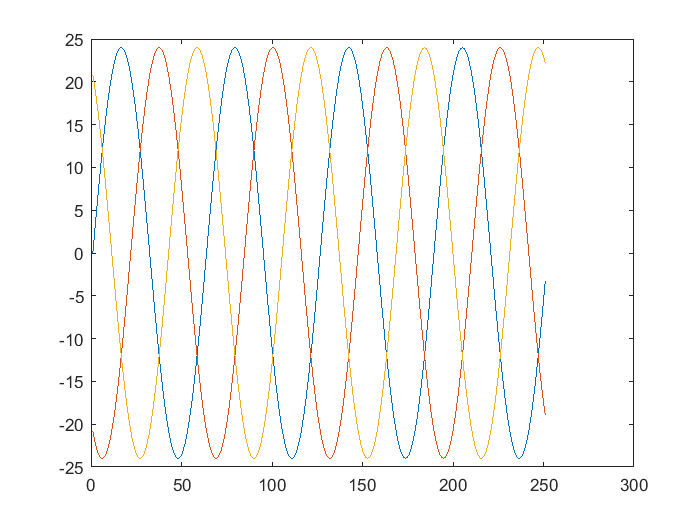

t = [0:0.1:25];
t2 = t+pi/7; %This is a displacement of the reference frame. it change the direction of dq vector
J_a = sin(t);
J_b = sin(t - 2*pi/3);
J_c = sin(t + 2*pi/3);
J_abc = 24*[J_a; J_b; J_c];
plot(J_abc');

Now we are going to transform the $V_{abc}$ to $V_{dq0}$ multiplying the trasform matrix by the $V_{abc}$  over time displacing $\pi/7 rad$ from the $V_{a}$  point of view, i.e $\theta = t+\pi / 7$:

displayFormula("[v_d;v_q;v_0]=" + sT_PC + "*[v_a;v_b;v_c]");

$$\left(\begin{array}{c} v_{d}\\ v_{q}\\ v_{0} \end{array}\right)=\sqrt{\frac{2}{3}}\,\left(\begin{array}{ccc} \cos\left(\theta \right) & \cos\left(\theta -\frac{2\,\pi }{3}\right) & \cos\left(\theta +\frac{2\,\pi }{3}\right)\\ -\sin\left(\theta \right) & -\sin\left(\theta -\frac{2\,\pi }{3}\right) & -\sin\left(\theta +\frac{2\,\pi }{3}\right)\\ \frac{1}{\sqrt{2}} & \frac{1}{\sqrt{2}} & \frac{1}{\sqrt{2}} \end{array}\right)\,\left(\begin{array}{c} v_{a}\\ v_{b}\\ v_{c} \end{array}\right)$$

The next graph shows the transformation of the $V_{abc}$ to the $V_{dq0}$. in this case the angle is dispaced $\pi/7 rad$ with a magnitud of 24V.

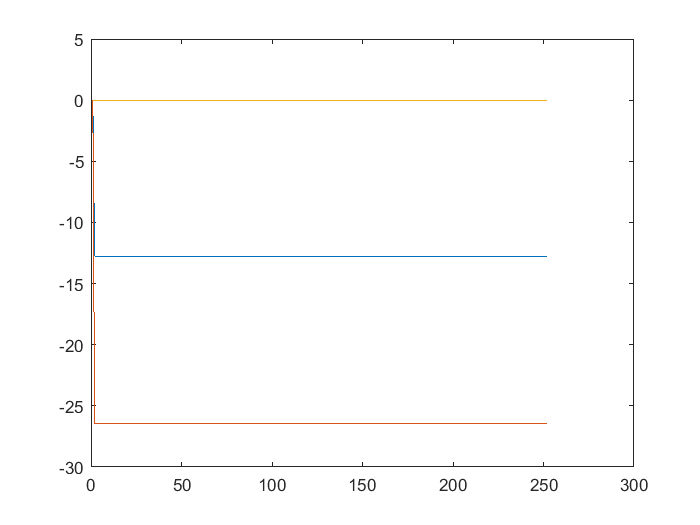

J_dq0 = [0;0;0];
for i = 1:size(t,2)
vT_PC = double(subs(T_PC, theta, t2(i)));
J_dq0 =[J_dq0 vT_PC*J_abc(:,i)];
end
plot(J_dq0');

Thre next example shows the same trasformation but in this time displaced 0 rad i.e $\theta = t+0$ .

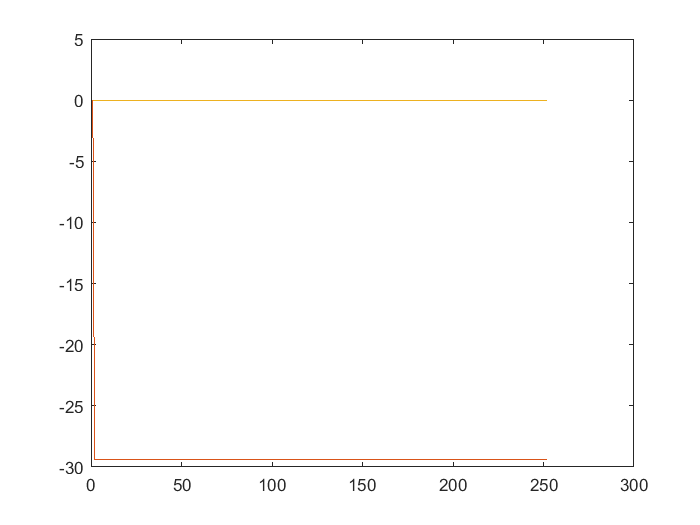

J_dq0 = [0;0;0];
for i = 1:size(t,2)
vT_PC = double(subs(T_PC, theta, t(i)));
J_dq0 =[J_dq0 vT_PC*J_abc(:,i)];
end
plot(J_dq0');

### ***The inverse Park-Clarke Transform/  park (power invariant):***

The inverse trasnform is as follows:

% The inverse Park-Clarke Transform/  park (power invariant)
siT_PC = "sqrt(2/3)*[cos(theta)          -sin(theta)            1/sqrt(2);"+ ...
                      "cos(theta-2*pi/3)   -sin(theta-2*pi/3)     1/sqrt(2);" + ...
                       "cos(theta+2*pi/3)   -sin(theta+2*pi/3)     1/sqrt(2)]";

displayFormula("iT_PC = "+ siT_PC);

$${\mathrm{iT}}_{\mathrm{PC}}=\sqrt{\frac{2}{3}}\,\left(\begin{array}{ccc} \cos\left(\theta \right) & -\sin\left(\theta \right) & \frac{1}{\sqrt{2}}\\ \cos\left(\theta -\frac{2\,\pi }{3}\right) & -\sin\left(\theta -\frac{2\,\pi }{3}\right) & \frac{1}{\sqrt{2}}\\ \cos\left(\theta +\frac{2\,\pi }{3}\right) & -\sin\left(\theta +\frac{2\,\pi }{3}\right) & \frac{1}{\sqrt{2}} \end{array}\right)$$

iT_PC = simplify(str2sym(siT_PC));

To recover from $V_{dq0}$ to $V_{abc}$ it is just needed to multiply the inverse transform by the $V_{dq0}$.

displayFormula("[v_a;v_b;v_c]=" + siT_PC + "*[v_d;v_q;v_0]");

$$\left(\begin{array}{c} v_{a}\\ v_{b}\\ v_{c} \end{array}\right)=\sqrt{\frac{2}{3}}\,\left(\begin{array}{ccc} \cos\left(\theta \right) & -\sin\left(\theta \right) & \frac{1}{\sqrt{2}}\\ \cos\left(\theta -\frac{2\,\pi }{3}\right) & -\sin\left(\theta -\frac{2\,\pi }{3}\right) & \frac{1}{\sqrt{2}}\\ \cos\left(\theta +\frac{2\,\pi }{3}\right) & -\sin\left(\theta +\frac{2\,\pi }{3}\right) & \frac{1}{\sqrt{2}} \end{array}\right)\,\left(\begin{array}{c} v_{d}\\ v_{q}\\ v_{0} \end{array}\right)$$

The example of the inverse park-Clarke is as follows defining the vector dq as the rectangular form for the vector $24 \angle \pi/7$:

[X,Y]=pol2cart(pi/7,24)

X = 21.6233

Y = 10.4132

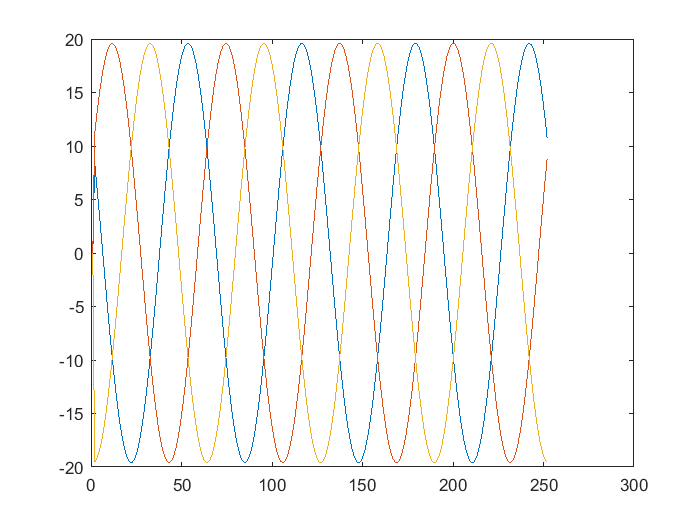

J_dq0 = [Y;X;0];
 
J_abc = [0;0;0];
for i = 1:size(t,2)    
viT_PC = double(subs(iT_PC, theta, t(i)));
J_abc =[J_abc viT_PC*J_dq0];
end
plot(J_abc');

In the next example is the inverse but using the vector of dq as $24 \angle (\pi/7 + 0.2)$ to see the displacment of the $V_{abc}$ resultant:

hold on
[X,Y]=pol2cart(pi/7+0.2,24)

X = 19.1234

Y = 14.5015

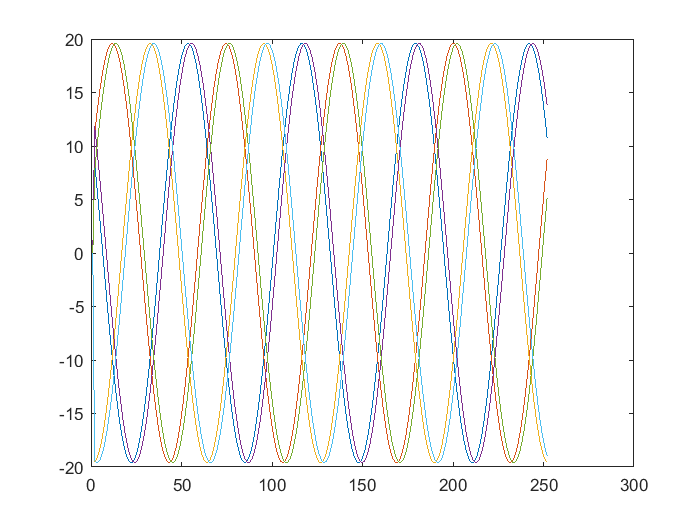

J_dq0 = [Y;X;0];
 
J_abc = [0;0;0];
for i = 1:size(t,2)
viT_PC = double(subs(iT_PC, theta, t(i)));
J_abc =[J_abc viT_PC*J_dq0];
end
plot(J_abc');


disp("*************************************************************************************")

*************************************************************************************


## The dq BLDC motor model

defining the BLDC model in abc form:

sLM = "[1/(L-M)    0        0;"+...
     "   0     1/(L-M)     0;"+ ...
     "   0        0     1/(L-M)] ";
LM = str2sym(sLM)

$$LM = \left(\begin{array}{ccc} \frac{1}{L-M} & 0 & 0\\ 0 & \frac{1}{L-M} & 0\\ 0 & 0 & \frac{1}{L-M} \end{array}\right)$$


sV_abc = "[V_a; V_b; V_c]";
V_abc = str2sym(sV_abc)

$$V\_abc = \left(\begin{array}{c} V_{a}\\ V_{b}\\ V_{c} \end{array}\right)$$


sRM = "[R    0    0;"+...
     "  0    R    0;"+ ...
     "  0    0    R] ";
RM = str2sym(sRM)

$$RM = \left(\begin{array}{ccc} R & 0 & 0\\ 0 & R & 0\\ 0 & 0 & R \end{array}\right)$$


sI_abc = "[i_a; i_b; i_c]";
I_abc = str2sym(sI_abc)

$$I\_abc = \left(\begin{array}{c} i_{a}\\ i_{b}\\ i_{c} \end{array}\right)$$


se_abc = "[e_a; e_b; e_c]";
e_abc = str2sym(se_abc)

$$e\_abc = \left(\begin{array}{c} e_{a}\\ e_{b}\\ e_{c} \end{array}\right)$$

BLDC equation:


$$\frac{d}{dt}\left(\begin{array}{c}
i_a \\
i_b \\
i_c 
\end{array}\right)=\left(\begin{array}{ccc}
\frac{1}{L-M} & 0 & 0\\
0 & \frac{1}{L-M} & 0\\
0 & 0 & \frac{1}{L-M}
\end{array}\right)\,{\left(\left(\begin{array}{c}
V_a \\
V_b \\
V_c 
\end{array}\right)-\left(\begin{array}{ccc}
R & 0 & 0\\
0 & R & 0\\
0 & 0 & R
\end{array}\right)\,\left(\begin{array}{c}
i_a \\
i_b \\
i_c 
\end{array}\right)-\left(\begin{array}{c}
e_a \\
e_b \\
e_c 
\end{array}\right)\right)}$$


sBLDC_abc = "diff(" + sI_abc +") == "+ sLM +"*" + "+[" + sV_abc +"-" +sRM +"*" + sI_abc+"- " + se_abc + "]";
displayFormula(sBLDC_abc);

$$\mathrm{diff}\left(\left(\begin{array}{c} i_{a}\\ i_{b}\\ i_{c} \end{array}\right)\right)=\left(\begin{array}{ccc} \frac{1}{L-M} & 0 & 0\\ 0 & \frac{1}{L-M} & 0\\ 0 & 0 & \frac{1}{L-M} \end{array}\right)\,\left(\left(\begin{array}{c} V_{a}\\ V_{b}\\ V_{c} \end{array}\right)-\left(\begin{array}{ccc} R & 0 & 0\\ 0 & R & 0\\ 0 & 0 & R \end{array}\right)\,\left(\begin{array}{c} i_{a}\\ i_{b}\\ i_{c} \end{array}\right)+\left(\begin{array}{c} -e_{a}\\ -e_{b}\\ -e_{c} \end{array}\right)\right)$$


disp("****************************************************************************************")

****************************************************************************************


now, we are going to multiply both sides of the equation by the Park-clarke transform $T_{PC}$


$$T_{PC}\frac{d}{dt}\left(\begin{array}{c}
i_a \\
i_b \\
i_c 
\end{array}\right)=\left(\begin{array}{ccc}
\frac{1}{L-M} & 0 & 0\\
0 & \frac{1}{L-M} & 0\\
0 & 0 & \frac{1}{L-M}
\end{array}\right)T_{PC}\,{\left(\left(\begin{array}{c}
V_a \\
V_b \\
V_c 
\end{array}\right)-\left(\begin{array}{ccc}
R & 0 & 0\\
0 & R & 0\\
0 & 0 & R
\end{array}\right)\,\left(\begin{array}{c}
i_a \\
i_b \\
i_c 
\end{array}\right)-\left(\begin{array}{c}
e_a \\
e_b \\
e_c 
\end{array}\right)\right)}$$


Getting  $\frac {d}{dt}T_{PC}$ in terms of  $T_{PC}$ (Park-Clarke transformation): 

displayFormula("T_PC = " + sT_PC,T_PC,T_PC);

$$T_{\mathrm{PC}}=\sqrt{\frac{2}{3}}\,\left(\begin{array}{ccc} \cos\left(\theta \right) & \cos\left(\theta -\frac{2\,\pi }{3}\right) & \cos\left(\theta +\frac{2\,\pi }{3}\right)\\ -\sin\left(\theta \right) & -\sin\left(\theta -\frac{2\,\pi }{3}\right) & -\sin\left(\theta +\frac{2\,\pi }{3}\right)\\ \frac{1}{\sqrt{2}} & \frac{1}{\sqrt{2}} & \frac{1}{\sqrt{2}} \end{array}\right)$$

then  $\frac {d}{d\theta}T_{PC}$ is equal to:

dT_PC = simplify(diff(T_PC,theta))

$$dT\_PC = \begin{array}{l} \left(\begin{array}{ccc} -\frac{\sqrt{6}\,\sin\left(\theta \right)}{3} & \frac{\sqrt{6}\,\sin\left(\theta +\frac{\pi }{3}\right)}{3} & -\frac{\sqrt{6}\,\sin\left(\sigma_{1}\right)}{3}\\ -\frac{\sqrt{6}\,\cos\left(\theta \right)}{3} & \frac{\sqrt{6}\,\cos\left(\theta +\frac{\pi }{3}\right)}{3} & -\frac{\sqrt{6}\,\cos\left(\sigma_{1}\right)}{3}\\ 0 & 0 & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\theta +\frac{2\,\pi }{3} \end{array}$$

Now, we want to define the derivative in terms of $T_{PC}$ and we obtained the $A_3$ matrix doing  $A_3 = \frac {dT_{PC}}{d\theta}T^{-1}_{PC}$ where $T^{-1}_{PC} = iT_{PC}$ 

A3 = simplify(dT_PC*iT_PC)

$$A3 = \left(\begin{array}{ccc} 0 & 1 & 0\\ -1 & 0 & 0\\ 0 & 0 & 0 \end{array}\right)$$

then

displayFormula("dT_PC = A3*T_PC*diff(theta,t)",[dT_PC A3 T_PC],[dT_PC A3 T_PC]);

$${\mathrm{dT}}_{\mathrm{PC}}=A_{3}\,T_{\mathrm{PC}}\,\frac{\partial }{\partial t}\theta$$

Now we want to find the element $T_{PC}\frac{d}{dt}\left(\begin{array}{c}
i_a \\
i_b \\
i_c 
\end{array}\right)$. we will do this using the rule for product derivative:


$$\frac{d}{dt}\left(T_{PC}I_{abc}\right) = \dot{T}_{PC}I_{abc}+T_{PC}\dot{I}_{abc}$$


$T_{PC}\frac{d}{dt}\left(\begin{array}{c}
i_a \\
i_b \\
i_c 
\end{array}\right) 

= 

\frac{d}{dt}\left(   T_{PC}I_{abc}\right) - \dot{T}_{PC}I_{abc}

= 

\dot{I}_{dq0} -A_3 I_{dq0}$ and hence


$$\dot{I}_{dq0} = A_3 I_{dq0} + L_M V_{dq0} - L_M R_M I _{dq0} - L_M e_{dq0}$$



$$\dot{I}_{dq0} = \left( A_3  -  L_M R_M  \right)   I_{dq0} + L_M V_{dq0} - L_M e_{dq0}$$



disp("****************************************************************************************")

****************************************************************************************


The result of the term


displayFormula("(A3-LM*RM)*i_dq",[A3,LM,RM,i_dq],[A3,LM,RM,i_dq])

$$\left(A_{3}-\mathrm{LM}\,\mathrm{RM}\right)\,i_{\mathrm{dq}}$$

is:

(A3-LM*RM)*i_dq

$$ans = \left(\begin{array}{c} i_{q}-\frac{R\,i_{d}}{L-M}\\ -i_{d}-\frac{R\,i_{q}}{L-M}\\ 0 \end{array}\right)$$

and eliminating the third element 0 to converto from $I_{dq0}$ to $I_{dq}$

A = [-R/(L-M)  (2*pi*fr); -(2*pi*fr)  -R/(L-M)]*[i_d;i_q]

$$A = \left(\begin{array}{c} 2\,\pi \,\mathrm{fr}\,i_{q}-\frac{R\,i_{d}}{L-M}\\ -2\,\pi \,\mathrm{fr}\,i_{d}-\frac{R\,i_{q}}{L-M} \end{array}\right)$$

Now we want to create a matrix for the Park-Clarke transform that returns only the two components dq from the balanced sine waves in this case $f_a,f_b,f_c$

displayFormula("T_PC*[f_a;f_b;f_c]",T_PC,T_PC)

$$T_{\mathrm{PC}}\,\left(\begin{array}{c} f_{a}\\ f_{b}\\ f_{c} \end{array}\right)$$

simplify(T_PC*[f_a;f_b;f_c])

$$ans = \left(\begin{array}{c} \frac{\sqrt{2}\,f_{b}\,\sin\left(\theta \right)}{2}-\frac{\sqrt{2}\,f_{c}\,\sin\left(\theta \right)}{2}+\frac{\sqrt{2}\,\sqrt{3}\,f_{a}\,\cos\left(\theta \right)}{3}-\frac{\sqrt{2}\,\sqrt{3}\,f_{b}\,\cos\left(\theta \right)}{6}-\frac{\sqrt{2}\,\sqrt{3}\,f_{c}\,\cos\left(\theta \right)}{6}\\ \frac{\sqrt{2}\,f_{b}\,\cos\left(\theta \right)}{2}-\frac{\sqrt{2}\,f_{c}\,\cos\left(\theta \right)}{2}-\frac{\sqrt{2}\,\sqrt{3}\,f_{a}\,\sin\left(\theta \right)}{3}+\frac{\sqrt{2}\,\sqrt{3}\,f_{b}\,\sin\left(\theta \right)}{6}+\frac{\sqrt{2}\,\sqrt{3}\,f_{c}\,\sin\left(\theta \right)}{6}\\ \frac{\sqrt{3}\,\left(f_{a}+f_{b}+f_{c}\right)}{3} \end{array}\right)$$

Considering the the sum of $f_a + f_b +f_c = 0$ because we have a balance loads in the motor, we can simplify:


% Park clarke transform eliminating the third element
T_PC = (sqrt(2)/2)*[sqrt(3)*cos(theta)  sin(theta) -sin(theta) ; ...
        -sqrt(3)*sin(theta) cos(theta) -cos(theta)]

$$T\_PC = \left(\begin{array}{ccc} \frac{\sqrt{2}\,\sqrt{3}\,\cos\left(\theta \right)}{2} & \frac{\sqrt{2}\,\sin\left(\theta \right)}{2} & -\frac{\sqrt{2}\,\sin\left(\theta \right)}{2}\\ -\frac{\sqrt{2}\,\sqrt{3}\,\sin\left(\theta \right)}{2} & \frac{\sqrt{2}\,\cos\left(\theta \right)}{2} & -\frac{\sqrt{2}\,\cos\left(\theta \right)}{2} \end{array}\right)$$

Then, we can use this new matix to transform the remainig elements such as $e_{abc}, V_{abc}$ for the corresponding dq form.

e_dq =(lamda*wm)*T_PC*[f_a;f_b;f_c]

$$e\_dq = \left(\begin{array}{c} \frac{\sqrt{2}\,f_{b}\,\mathrm{lamda}\,\mathrm{wm}\,\sin\left(\theta \right)}{2}-\frac{\sqrt{2}\,f_{c}\,\mathrm{lamda}\,\mathrm{wm}\,\sin\left(\theta \right)}{2}+\frac{\sqrt{2}\,\sqrt{3}\,f_{a}\,\mathrm{lamda}\,\mathrm{wm}\,\cos\left(\theta \right)}{2}\\ \frac{\sqrt{2}\,f_{b}\,\mathrm{lamda}\,\mathrm{wm}\,\cos\left(\theta \right)}{2}-\frac{\sqrt{2}\,f_{c}\,\mathrm{lamda}\,\mathrm{wm}\,\cos\left(\theta \right)}{2}-\frac{\sqrt{2}\,\sqrt{3}\,f_{a}\,\mathrm{lamda}\,\mathrm{wm}\,\sin\left(\theta \right)}{2} \end{array}\right)$$

disp("****************************************************************************************")

****************************************************************************************



i_dq = [i_d; i_q];
v_dq = [V_d;V_q];

LR = [-R/(L-M)  1; -1  -R/(L-M)];

% e_dq =(lamda*wm)*PC_T*f;
% v_dq = v*(PC_T*f);

di_dq = LR*i_dq + (1/(L-M))*v_dq - (1/(L-M))*e_dq

$$di\_dq = \left(\begin{array}{c} i_{q}+\frac{V_{d}}{L-M}-\frac{\frac{\sqrt{2}\,f_{b}\,\mathrm{lamda}\,\mathrm{wm}\,\sin\left(\theta \right)}{2}-\frac{\sqrt{2}\,f_{c}\,\mathrm{lamda}\,\mathrm{wm}\,\sin\left(\theta \right)}{2}+\frac{\sqrt{2}\,\sqrt{3}\,f_{a}\,\mathrm{lamda}\,\mathrm{wm}\,\cos\left(\theta \right)}{2}}{L-M}-\frac{R\,i_{d}}{L-M}\\ \frac{V_{q}}{L-M}-i_{d}+\frac{\frac{\sqrt{2}\,f_{c}\,\mathrm{lamda}\,\mathrm{wm}\,\cos\left(\theta \right)}{2}-\frac{\sqrt{2}\,f_{b}\,\mathrm{lamda}\,\mathrm{wm}\,\cos\left(\theta \right)}{2}+\frac{\sqrt{2}\,\sqrt{3}\,f_{a}\,\mathrm{lamda}\,\mathrm{wm}\,\sin\left(\theta \right)}{2}}{L-M}-\frac{R\,i_{q}}{L-M} \end{array}\right)$$


simplify(di_dq)

$$ans = \left(\begin{array}{c} -\frac{2\,M\,i_{q}-2\,L\,i_{q}-2\,V_{d}+2\,R\,i_{d}+\sqrt{6}\,f_{a}\,\mathrm{lamda}\,\mathrm{wm}\,\cos\left(\theta \right)+\sqrt{2}\,f_{b}\,\mathrm{lamda}\,\mathrm{wm}\,\sin\left(\theta \right)-\sqrt{2}\,f_{c}\,\mathrm{lamda}\,\mathrm{wm}\,\sin\left(\theta \right)}{2\,\left(L-M\right)}\\ \frac{2\,V_{q}-2\,L\,i_{d}+2\,M\,i_{d}-2\,R\,i_{q}-\sqrt{2}\,f_{b}\,\mathrm{lamda}\,\mathrm{wm}\,\cos\left(\theta \right)+\sqrt{2}\,f_{c}\,\mathrm{lamda}\,\mathrm{wm}\,\cos\left(\theta \right)+\sqrt{6}\,f_{a}\,\mathrm{lamda}\,\mathrm{wm}\,\sin\left(\theta \right)}{2\,\left(L-M\right)} \end{array}\right)$$